## Signals

•**Analog** signal: a continuous function of time $s(t)$

•**Discrete time **signal: sequence of values (“samples”) of an analog signal


$$s[k]=s(t_k), k=...,-1,-2,0,1,...$$


Consider the continuous function of time given by,


$$s(t) = A \sin(2\pi \phi(t))$$



$$\phi(t) = a_1 t + a_2 t^2 +a_3 t^3$$


Clearly, this is an oscillatory signal. The function $\phi(t)$ is the **instantaneous phase** of the oscillations, and $A$is the **amplitude** of the oscillations.

The quantities $A$, $a_i$, $i = 1, 2, 3$, are called the parameters of the signal. For different values of these parameters, we get different functions of time but they all belong to the same family of functions. Members of this family are called **quadratic chirps**. This name comes from the fact that the **instantaneous frequency** of the signal,

$f(t) = \frac{1}{2\pi} \frac{d\phi(t)}{dt}$,

is changing with time -- such a signal is called a chirp -- and it is a quadratic function of time. 

We can construct a discrete time quadratic chirp signal by sampling the analog signal at uniformly spaced time instants.

First, let us pick some values for the parameters.

a1=5;
a2=3;
a3=3;
A = 10;

Next, we fix the time interval over which we want to obtain the samples.

sigLen = 1.0; %seconds

We need to fix the interval between consecutive sample times. This is called the **sampling interval**.

samplIntrvl = 0.01; %seconds

Obtain the vector of sampling times.

timeVec = 0:samplIntrvl:sigLen;

Obtain the instantaneous phase at the sample times.

phaseVec = a1*timeVec + a2*timeVec.^2 + a3*timeVec.^3;

Obtain the samples of the signal.

sigVec = A * sin(2*pi*phaseVec);

Plot the discrete time signal. The sample values are shown as open circles. They are joined by straight lines to make the signal visually clear.

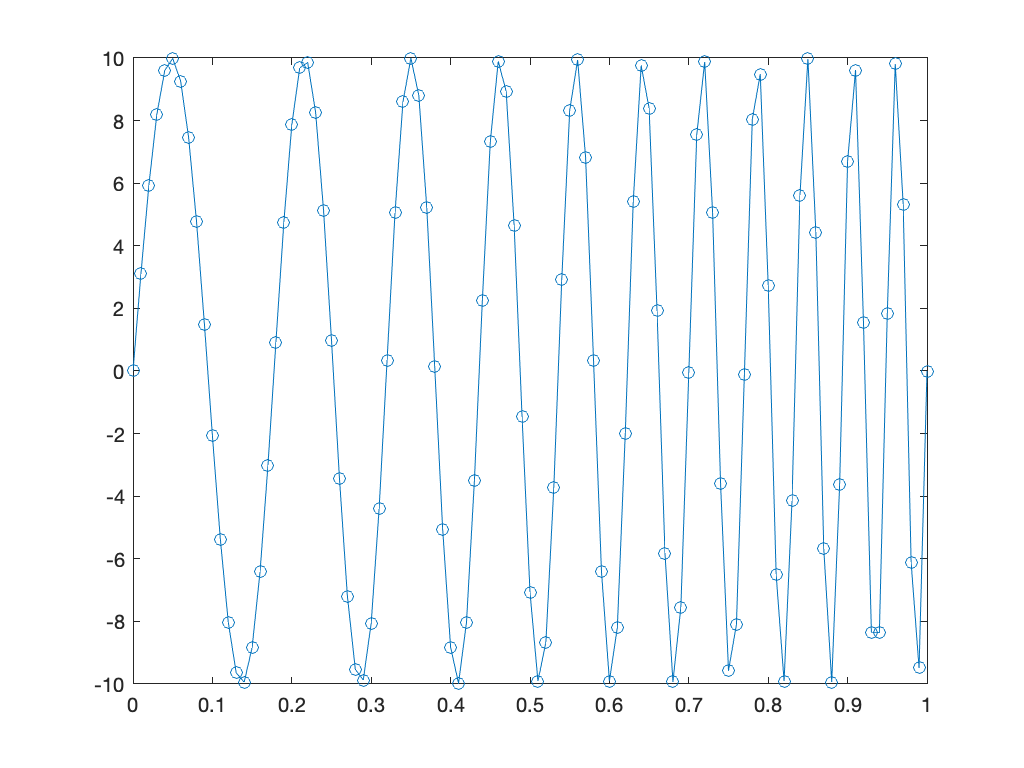

plot(timeVec,sigVec,'-o');